clc; clear;

gridSize = 10;  % Example grid size (10x10)
% Random initial state
grid = randi([0 1], gridSize, gridSize); 

generations = 50;


This generates the actual 10 by 10 **data** (cell states) in the grid, with values `0` and `1 at random postions`.

- **0:** Represents a dead cell.

- **1:** Represents a live cell.

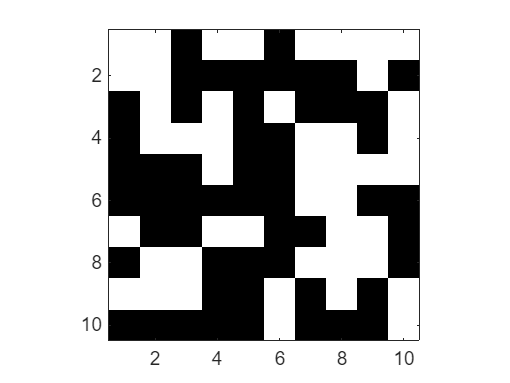


imagesc(grid); colormap(gray); axis equal tight;

This command visualizes a matrix `grid` as a grayscale image, where:

- The pixel sizes are equal and tightly fit the image dimensions.

- The grayscale color map ensures distinct visualization for binary states (`0 = black`, `1 = white`).

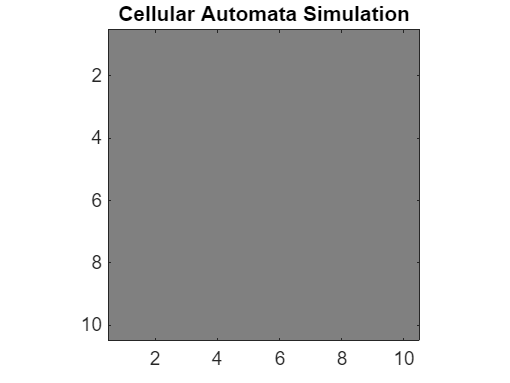

function liveNeighbors = countLiveNeighbors(grid, x, y)
    % Input:
    % grid- a 2D matrix representing the state of the cellular automaton (1 for live cells, 0 for dead cells).
    % x,y -  the coordinates of the target cell in the grid.
    % Output:

    % LiveNeighbors - the number of neighboring cells that are live (value 1).
    [rows, cols] = size(grid); % stores the dimensions of the grid
    % define the relative positions of all eight neighboring cells around (x, y).
    neighbors = [-1 -1; -1 0; -1 1; 0 -1; 0 1; 1 -1; 1 0; 1 1];
    liveNeighbors = 0; % instantiate the number of live cells.
    
    % Iterate through all possible neighbors by adding the offsets from the neighbors array to the coordinates (x, y).
    for i = 1:size(neighbors, 1)
        nx = x + neighbors(i, 1);
        ny = y + neighbors(i, 2);

        % Define the boundary conditions ( for toroidal grid)
        % If the neighbor coordinates go out of bounds, the function wraps
        % around to the opposite edge of the grid.
        if nx < 1, nx = rows; elseif nx > rows, nx = 1; end
        if ny < 1, ny = cols; elseif ny > cols, ny = 1; end

        % nx < 1: wrap to the last row.
        %nx > rows: wrap to the first row.
        %ny < 1: wrap to the last column.
        %ny > cols: wrap to the first column.

        liveNeighbors = liveNeighbors + grid(nx, ny); %  count the number of live neighbors for a given cell (x, y) in the grid.
    end
end


function newGrid = updateGrid(grid)
    % Input:
    % grid: a 2D matrix representing the current state of the automaton (1 for live cells, 0 for dead cells).
    % Output:
    % newGrid: a 2D matrix with the updated state after one simulation step.
    [rows, cols] = size(grid);
    newGrid = grid; % create a copy of grid to store the updated grid.

    for x = 1:rows
        for y = 1:cols
            % Call the countLiveNeighbors function to get the number of live neighbors for the current cell (x, y).
            liveNeighbors = countLiveNeighbors(grid, x, y);

            if grid(x, y) == 0  % If cell is alive
                % Underpopulation: A live cell with fewer than two live neighbors dies.
                % Overpopulation: A live cell with more than three live neighbors dies.
                % Survival: A live cell with two or three live neighbors survives to the next generation.
                % That is the live cell remains alive if it does not meet the conditions for death (i.e., it has exactly 2 or 3 neighbors).
                if liveNeighbors < 2 || liveNeighbors > 3
                    newGrid(x, y) = 1;  % Cell dies
                end
            else  % If cell is dead
                % Reproduction: A dead cell with exactly three live neighbors becomes alive.
                if liveNeighbors == 3
                    newGrid(x, y) = 0;  % Cell becomes alive
                end
            end
        end
    end
end


% Visualize the state of a cellular automata grid
function visualize(grid)
    % Input:
    % grid: A 2D matrix representing the current state of the grid (1 for live cells, 0 for dead cells).
    imagesc(grid);
    colormap(gray);
    axis equal tight;
    title('Cellular Automata Simulation');
    drawnow;
end



for gen = 1:generations
    visualize(grid);
    grid = updateGrid(grid);
    pause(0.5);  % Pause for visualization speed
end
